%% UTADIS Pipeline: Training + Prediction (full display)

% === 1. Load training data ===
filename_train = 'data_train_.csv';
opts = detectImportOptions(filename_train, 'Encoding', 'UTF-8');
opts = setvartype(opts, {'Building_type','District','Condition'}, 'string');
data_train = readtable(filename_train, opts);

data_train(:,6) = [];
data_train(:,6) = []

data_train = 50×6 table
    Var1      Price       Surface      Building_type         District           Condition    
    ____    __________    _______    _________________    ______________    _________________

      1      9.269e+05      71.3     "blok mieszkalny"    "Ołbin"           "do wykończenia" 
      2        2.5e+06       105     "blok mieszkalny"    "Stare Miasto"    "bardzo dobry"   
      3      1.194e+06      67.9     "blok mieszkalny"    "Kleczków"        "do wykończenia" 
      4     9.3412e+05     91.35     "apartamentowiec"    "Krzyki"          "do wykończenia" 
      5       5.75e+05     46.54     "blok mieszkalny"    "Krzyki"          "do remontu"     
      6       5.69e+05     36.12     "blok mieszkalny"    "Jagodno"         "wysoki standard"
      7     5.0453e


unique(data_train.Building_type);
unique(data_train.District);
unique(data_train.Condition);

% === 2. Manual transformation of categorical variables (for training) ===

% 2.1 Building_type (mapping)
building_type_keys = ["apartamentowiec", "blok mieszkalny", "dom wielorodzinny", "dom wolnostojący", "kamienica"];
building_type_values = [3, 2, 4, 5, 1];
building_type_map = containers.Map(building_type_keys, building_type_values);

bt_raw = strtrim(data_train.Building_type);
bt_mapped = zeros(size(bt_raw));

for i = 1:length(bt_raw)
    if isKey(building_type_map, bt_raw(i))
        bt_mapped(i) = building_type_map(bt_raw(i));
    else
        bt_mapped(i) = 0;
    end
end

data_train.Building_type = bt_mapped;

% 2.2 District (mapping)
district_keys_center = ["Stare Miasto"];
district_keys_near_center = ["Nadodrze", "Plac Grunwaldzki", "Ołbin", "Przedmieście Oławskie", ...
                             "Szczepin", "Krzyki", "Grabiszyn", "Gajowice", "Huby", "Tarnogaj", ...
                             "Powstańców Śląskich", "Borek", "Gaj"];

dist_raw = strtrim(data_train.District);
dist_mapped = ones(size(dist_raw));

for i = 1:length(dist_raw)
    if any(dist_raw(i) == district_keys_center)
        dist_mapped(i) = 3;
    elseif any(dist_raw(i) == district_keys_near_center)
        dist_mapped(i) = 2;
    else
        dist_mapped(i) = 1;
    end
end

data_train.District = dist_mapped;

% 2.3 Condition (mapping)
condition_keys = ["-", "bardzo dobry", "deweloperski", "do odświeżenia", ...
                  "do remontu", "do wykończenia", "dobry", "nowe wykończone", "wysoki standard"];
condition_values = [0, 6, 2, 3, 1, 4, 5, 8, 7];
condition_map = containers.Map(condition_keys, condition_values);

cond_raw = strtrim(data_train.Condition);
cond_mapped = zeros(size(cond_raw));

for i = 1:length(cond_raw)
    if isKey(condition_map, cond_raw(i))
        cond_mapped(i) = condition_map(cond_raw(i));
    else
        cond_mapped(i) = 2; % Default assignment
    end
end

data_train.Condition = cond_mapped;

% === 3. Load test data ===
filename_test = 'data_predict_.csv';
opts_test = detectImportOptions(filename_test, 'Encoding', 'UTF-8');
opts_test = setvartype(opts_test, {'Building_type','District','Condition'}, 'string');
data_test = readtable(filename_test, opts_test);

data_test(:,6) = [];
data_test(:,6) = []

data_test = 50×6 table
    Var1      Price       Surface      Building_type             District                Condition    
    ____    __________    _______    _________________    _______________________    _________________

      1       6.92e+05     54.04     "blok mieszkalny"    "Poświętne"                "bardzo dobry"   
      2       1.02e+06     68.72     "blok mieszkalny"    "Księże"                   "wysoki standard"
      3     7.0668e+05     48.02     "blok mieszkalny"    "Polanowice"               "do wykończenia" 
      4       6.55e+05     68.69     "blok mieszkalny"    "Maślice"                  "do wykończenia" 
      5       6.49e+05     39.11     "apartamentowiec"    "Ołtaszyn"                 "wysoki standard"
      6      1.338e+06     81.92     "blok mieszkal


unique(data_test.Building_type);
unique(data_test.District);
unique(data_test.Condition);

% === 4. Encode categorical variables (for test data) ===

% Building_type
bt_raw_test = strtrim(data_test.Building_type);
bt_mapped_test = zeros(size(bt_raw_test));

for i = 1:length(bt_raw_test)
    if isKey(building_type_map, bt_raw_test(i))
        bt_mapped_test(i) = building_type_map(bt_raw_test(i));
    else
        bt_mapped_test(i) = 0;
    end
end

data_test.Building_type = bt_mapped_test;

% District
dist_raw_test = strtrim(data_test.District);
dist_mapped_test = ones(size(dist_raw_test));

for i = 1:length(dist_raw_test)
    if any(dist_raw_test(i) == district_keys_center)
        dist_mapped_test(i) = 3;
    elseif any(dist_raw_test(i) == district_keys_near_center)
        dist_mapped_test(i) = 2;
    else
        dist_mapped_test(i) = 1;
    end
end

data_test.District = dist_mapped_test;

% Condition
cond_raw_test = strtrim(data_test.Condition);
cond_mapped_test = zeros(size(cond_raw_test));

for i = 1:length(cond_raw_test)
    if isKey(condition_map, cond_raw_test(i))
        cond_mapped_test(i) = condition_map(cond_raw_test(i));
    else
        cond_mapped_test(i) = 2;
    end
end

data_test.Condition = cond_mapped_test;

% === 5. Display tables and matrices ===

disp('Training data table (after encoding):');

Training data table (after encoding):


disp(data_train)

    Var1      Price       Surface    Building_type    District    Condition
    ____    __________    _______    _____________    ________    _________

      1      9.269e+05      71.3           2             2            4    
      2        2.5e+06       105           2             3            6    
      3      1.194e+06      67.9           2             1            4    
      4     9.3412e+05     91.35           3             2            4    
      5       5.75e+05     46.54           2             2            1    
      6       5.69e+05     36.12           2             1            7    
      7     5.0453e+05     38.81           2             2            5    
      8       5.07e+05     35.63           2             2            4    
      9       5.59e+05      39.3   


dtrain = table2array(data_train);
dtrain(:, 1) = []; % assuming first column is ID - remove it

disp('Training matrix (dtrain) without ID:');

Training matrix (dtrain) without ID:


disp(dtrain)

   1.0e+06 *

    0.9269    0.0001    0.0000    0.0000    0.0000
    2.5000    0.0001    0.0000    0.0000    0.0000
    1.1940    0.0001    0.0000    0.0000    0.0000
    0.9341    0.0001    0.0000    0.0000    0.0000
    0.5750    0.0000    0.0000    0.0000    0.0000
    0.5690    0.0000    0.0000    0.0000    0.0000
    0.5045    0.0000    0.0000    0.0000    0.0000
    0.5070    0.0000    0.0000    0.0000    0.0000
    0.5590    0.0000    0.0000    0.0000    0.0000
    0.5790    0.0000    0.0000    0.0000    0.0000
    0.4950    0.0000    0.0000    0.0000    0.0000
    0.6835    0.0001    0.0000    0.0000    0.0000
    0.8219    0.0001    0.0000    0.0000    0.0000
    0.8846    0.0001    0.0000    0.0000    0.0000
    0.7490    0.0001    0.0000    0.0000    0.0000
    0.6350    0.0000    0.0000    0.0000    0.0000
    0.4890    0.0001    0.0000    0.0000    0.0000
    0.3498    0.0000    0.0000    0.0000    0.0000
    0.7186    0.0001    0.0000    0.0000    0.0000
    1.0587    0.0


disp('Test data table (after encoding):');

Test data table (after encoding):


disp(data_test)

    Var1      Price       Surface    Building_type    District    Condition
    ____    __________    _______    _____________    ________    _________

      1       6.92e+05     54.04           2             1            6    
      2       1.02e+06     68.72           2             1            7    
      3     7.0668e+05     48.02           2             1            4    
      4       6.55e+05     68.69           2             1            4    
      5       6.49e+05     39.11           3             1            7    
      6      1.338e+06     81.92           2             1            4    
      7        7.1e+05        63           2             1            7    
      8     4.9135e+05     29.23           3             2            4    
      9       7.03e+05     70.43   


dtest = table2array(data_test);
dtest(:, 1) = [];

disp('Test matrix (dtest) without ID:');

Test matrix (dtest) without ID:


disp(dtest)

   1.0e+06 *

    0.6920    0.0001    0.0000    0.0000    0.0000
    1.0200    0.0001    0.0000    0.0000    0.0000
    0.7067    0.0000    0.0000    0.0000    0.0000
    0.6550    0.0001    0.0000    0.0000    0.0000
    0.6490    0.0000    0.0000    0.0000    0.0000
    1.3380    0.0001    0.0000    0.0000    0.0000
    0.7100    0.0001    0.0000    0.0000    0.0000
    0.4914    0.0000    0.0000    0.0000    0.0000
    0.7030    0.0001    0.0000    0.0000    0.0000
    0.3690    0.0000    0.0000    0.0000    0.0000
    0.6120    0.0000    0.0000    0.0000    0.0000
    0.9379    0.0001    0.0000    0.0000    0.0000
    0.7915    0.0000    0.0000    0.0000    0.0000
    0.5110    0.0000    0.0000    0.0000    0.0000
    1.0138    0.0001    0.0000    0.0000    0.0000
    0.7713    0.0001    0.0000    0.0000    0.0000
    0.6686    0.0001    0.0000    0.0000    0.0000
    0.7000    0.0001    0.0000    0.0000    0.0000
    0.7910    0.0001    0.0000    0.0000    0.0000
    0.9246    0.0


min_dtrain = min(dtrain, [], 1);
max_dtrain = max(dtrain, [], 1);

% Prevent division by zero
range_dtrain = max_dtrain - min_dtrain;
range_dtrain(range_dtrain == 0) = 1;

% Normalize dtrain
dtrain_norm = (dtrain - min_dtrain) ./ range_dtrain;

% Normalize dtest using parameters from dtrain
dtest_norm = (dtest - min_dtrain) ./ range_dtrain;

% Display results
disp('Min-max normalized dtrain matrix:');

Min-max normalized dtrain matrix:


disp(dtrain_norm)

    0.2684    0.6021    0.3333    0.5000    0.4286
    1.0000    1.0000    0.3333    1.0000    0.7143
    0.3926    0.5619    0.3333         0    0.4286
    0.2718    0.8388    0.6667    0.5000    0.4286
    0.1047    0.3097    0.3333    0.5000         0
    0.1019    0.1867    0.3333         0    0.8571
    0.0720    0.2184    0.3333    0.5000    0.5714
    0.0731    0.1809    0.3333    0.5000    0.4286
    0.0973    0.2242    0.6667         0    0.8571
    0.1066    0.3270    0.3333    0.5000    0.5714
    0.0675    0.1557    0.3333    0.5000    0.5714
    0.1552    0.4332    0.3333         0    0.4286
    0.2196    0.6421    0.3333         0    0.7143
    0.2487    0.3613    0.3333    1.0000    0.4286
    0.1857    0.5041    0.6667         0    0.8571
    0.1326    0.2937    0.6667    0.5000    0.7143
    0.0647    0.4500         0    0.5000         0
         0         0    0.3333    0.5000    0.7143
    0.1715    0.3777    0.3333    0.5000    0.4286
    0.3297    0.7292    0.3333 


disp('Min-max normalized dtest matrix:');

Min-max normalized dtest matrix:


disp(dtest_norm)

    0.1591    0.3983    0.3333         0    0.7143
    0.3117    0.5716    0.3333         0    0.8571
    0.1660    0.3272    0.3333         0    0.4286
    0.1419    0.5713    0.3333         0    0.4286
    0.1392    0.2220    0.6667         0    0.8571
    0.4596    0.7275    0.3333         0    0.4286
    0.1675    0.5041    0.3333         0    0.8571
    0.0658    0.1053    0.6667    0.5000    0.4286
    0.1643    0.5918    0.3333         0    0.4286
    0.0089    0.1124         0    0.5000    0.5714
    0.1219    0.2234    0.6667         0    0.8571
    0.2735    0.7762    0.6667         0    0.4286
    0.2054    0.1579    0.6667    0.5000    0.8571
    0.0750    0.0847    0.6667    1.0000    0.4286
    0.3088    0.5650    0.3333         0    0.4286
    0.1960    0.4994    0.3333         0    0.4286
    0.1483    0.3656    0.3333    0.5000    0.4286
    0.1629    0.5690         0    1.0000    0.7143
    0.2052    0.5371    0.6667         0    0.8571
    0.2673    0.3688    0.3333 

Indicative example

% 2 is taken, 1 is not taken
A = dtrain_norm;
D = 3;
B=[1 1 1 2 1 1 1 1 2 2 1 1 2 1 2 2 1 1 1 1 1 1 2 1 1 2 2 1 1 1 1 1 2 1 1 1 2 1 1 2 2 1 2 2 1 2 1 1 1 1]';

[w, lambda, U, predicted_classes,R, br] = UTADIS(A,B,D);
w % Partial weight vectors – estimated utility values for each interval of each feature

w =          0         0         0
    0.0455         0         0
         0    0.0012    0.9153
    0.0042         0         0
         0    0.0338         0


predicted_classes % obviously lol

predicted_classes =      1
     2
     1
     1
     1
     1
     1
     1
     1
     2


lambda % Estimated thresholds between classes – boundary values that separate decision classes

lambda = 0.0693

U % Alternatives' utilities – global utility value for each alternative

U =     0.0593
    0.0835
    0.0551
    0.0605
    0.0464
    0.0593
    0.0581
    0.0385
    0.0657
    0.0729



true_classes_test = [...
2 1 1 2 2 1 2 1 1 1 ...
2 1 1 1 1 1 2 2 1 1 ...
2 1 1 1 1 1 1 1 1 2 1 ...
1 1 1 1 1 2 1 1 1 1 ...
1 2 1 1 1 1 2 1 1]';

% In test prediction:
[predicted_test_classes, acc] = predict_UTADIS(dtest_norm, w, lambda, R, br, true_classes_test);

fprintf('Test accuracy: %.2f%%\n', acc);

Test accuracy: 0.64%


% Confusion matrix
conf_mat_test = confusionmat(true_classes_test, predicted_test_classes);

% Display matrix with labels
disp('Confusion Matrix:');

Confusion Matrix:


disp(array2table(conf_mat_test, ...
    'VariableNames', {'Predicted_1', 'Predicted_2'}, ...
    'RowNames', {'Actual_1', 'Actual_2'}));

                Predicted_1    Predicted_2
                ___________    ___________

    Actual_1        27             11     
    Actual_2         7              5     



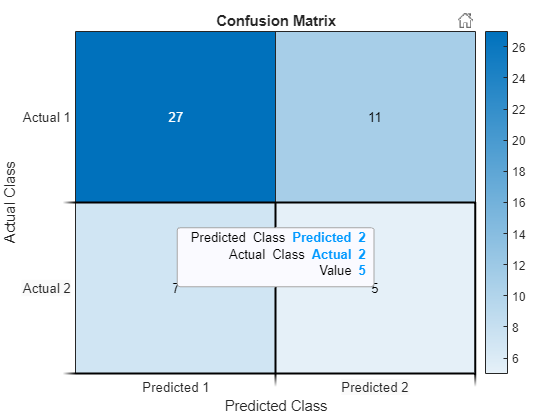


% Visualization as heatmap
figure;
heatmap({'Predicted 1', 'Predicted 2'}, {'Actual 1', 'Actual 2'}, conf_mat_test, ...
    'Title', 'Confusion Matrix', ...
    'XLabel', 'Predicted Class', ...
    'YLabel', 'Actual Class', ...
    'ColorbarVisible', 'on');

A_test = dtest_norm;
% A_test - new data to classify (p alternatives, n criteria)

[p, n] = size(A_test);
X_test = zeros(n, D, p);          % partial utilities
X_test_2d = nan(p, n * D);        % 2D matrix for classification input
R_test = (max(A_test) - min(A_test)) ./ D;  % step sizes for interpolation

% calculating partial utilities for new data
for i = 1:p
    for j = 1:n
        for k = 1:D
            if A_test(i,j) <= br(k+1,j)
                X_test(j,:,i) = [ones(1,k-1), 1 - (br(k+1,j) - A_test(i,j)) / R_test(j), zeros(1,D-k)];
                break;
            end
        end
    end
    X_test_2d(i,:) = reshape(X_test(:,:,i)', 1, n*D);
end

% Calculating global utilities
U_test = X_test_2d * w(:);

% Assigning classes based on lambda threshold
predicted_classes_test = zeros(p, 1);
for i = 1:p
    if U_test(i) < lambda
        predicted_classes_test(i) = 1;
    else
        predicted_classes_test(i) = 2;
    end
end

% === 6. Evaluation of classification performance ===

% Accuracy (classification performance)
accuracy = sum(predicted_classes == B) / length(B);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 88.00%



% Confusion matrix
conf_mat = confusionmat(B, predicted_classes);

% Display confusion matrix with labels
disp('Confusion Matrix:');

Confusion Matrix:


disp(array2table(conf_mat, ...
    'VariableNames', {'Predicted_1', 'Predicted_2'}, ...
    'RowNames', {'Actual_1', 'Actual_2'}));

                Predicted_1    Predicted_2
                ___________    ___________

    Actual_1        30              4     
    Actual_2         2             14     



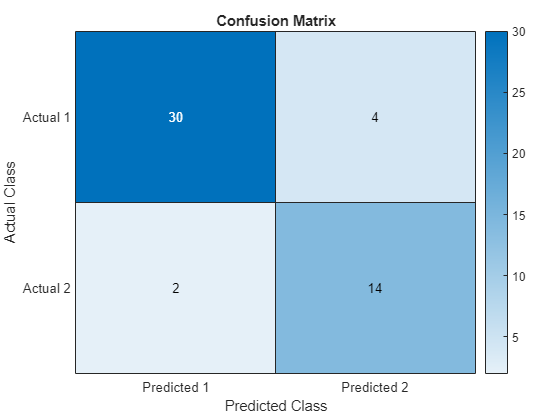


% Visualization as heatmap
figure;
heatmap({'Predicted 1', 'Predicted 2'}, {'Actual 1', 'Actual 2'}, conf_mat, ...
    'Title', 'Confusion Matrix', ...
    'XLabel', 'Predicted Class', ...
    'YLabel', 'Actual Class', ...
    'ColorbarVisible', 'on');

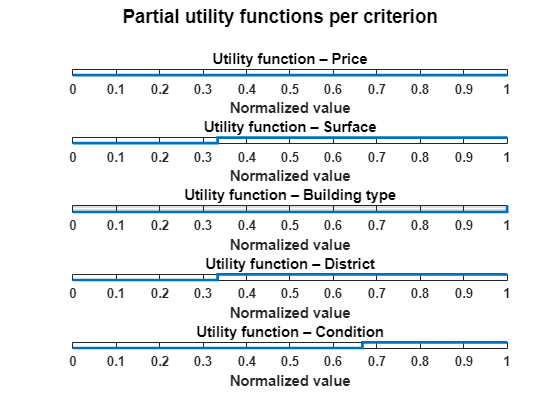

criterion_names = {'Price', 'Surface', 'Building type', 'District', 'Condition'};
[n, D] = size(w);
x = linspace(0, 1, D+1); % Intervals for X axis

figure;
for j = 1:n
    subplot(n, 1, j); % Stacked plots
    stairs(x, [0, cumsum(w(j,:))], 'LineWidth', 2);
    title(['Utility function – ', criterion_names{j}], 'FontSize', 12, 'FontWeight', 'bold'); % Powiększ tytuł
    xlabel('Normalized value', 'FontSize', 10, 'FontWeight', 'bold'); % Powiększ i pogrub etykietę osi X
    ylabel('Utility', 'FontSize', 10, 'FontWeight', 'bold'); % Powiększ i pogrub etykietę osi Y
    
    % Ustawienie zakresu osi Y
    ymax = max(cumsum(w(j,:)));
    if ymax == 0
        ylim([0, 1]); % Default range if flat function
    else
        ylim([0, ymax]);
    end
    
    % Ustawienia podziałek osi
    set(gca, 'FontSize', 10, 'FontWeight', 'bold'); % Zwiększ czcionkę na osiach
    
    % Dodanie więcej podziałek na osi X i Y
    xticks(0:0.1:1); % Ustawienia podziałek na osi X (można dostosować)
    yticks(0:0.2:ymax); % Ustawienia podziałek na osi Y (można dostosować)

    % Ustawienia siatki
    grid on;
end

sgtitle('Partial utility functions per criterion', 'FontSize', 14, 'FontWeight', 'bold'); % Powiększ tytuł całej figury


disp(table(U, B, predicted_classes))

       U        B    predicted_classes
    ________    _    _________________

    0.059298    1            1        
    0.083469    1            2        
    0.055127    1            1        
    0.060538    2            1        
    0.046409    1            1        
    0.059298    1            1        
    0.058132    1            1        
    0.038509    1            1        
    0.065659    2            1        
    0.072931    2            2        
    0.049581    1            1        
    0.055127    1            1        
    0.079298    2            2        
    0.059298    1            1        
    0.080538    2            2        
    0.079298    2            2        
     0.04963    1            1        
     0.03801    1            1        
    0.059298    1            1        
    0.055127    1            1        
    0.041665    1            1        


FUNCTIONS

% Functions for data handling

function [encoded, map] = label_encode(column)
    [map, ~, idx] = unique(column);
    encoded = idx - 1;
end

function encoded = encode_with_map(column, map)
    encoded = zeros(length(column),1) - 1;
    for i = 1:length(map)
        encoded(strcmp(column, map(i))) = i-1;
    end
end

%MAIN UTADIS FUNCTION

function [w, lambda, U, predicted_classes,R,br] = UTADIS(A, B, D)
% UTADIS method (estimation of utility function and class thresholds)
% A - (m x n) alternatives matrix
% B - (m x 1) class assignments (integers from 1 to K)
% D - number of intervals per criterion

[m, n] = size(A); % number of alternatives m and criteria n
K = max(B); % number of classes

% Step 1: Interval division
br = nan(D+1,n); % Table with breakpoints; (D+1) rows for D intervals
R = (max(A) - min(A)) ./ D; % Step sizes


for i = 1:D+1
    br(i,:) = min(A) + (i-1)*R;
end

% Step 2: Partial utility calculation
X = zeros(n, D, m); % 3D matrix for partial utility coefficients
X_2d = nan(m, n*D); % Flattened 2D version

for i = 1:m
    for j = 1:n
        for k = 1:D
            if A(i,j) <= br(k+1,j)
                X(j,:,i) = [ones(1,k-1), 1 - (br(k+1,j) - A(i,j)) / R(j), zeros(1,D-k)];
                break;
            end
        end
    end
    X_2d(i,:) = reshape(X(:,:,i)', 1, n*D);
end

% Step 3: Build LP. Partial weights w, lambda thresholds, e⁺, e⁻ error terms
%n*D + (K-1) + 2*m;
obj = [zeros(1, n*D), zeros(1, K-1), ones(1, 2*m)];

epsilon = 1e-2;
A_lp = [];
rhs_lp = [];
sense_lp = [];

for i = 1:m
    row = zeros(1, n*D + (K-1) + 2*m);
    row(1:n*D) = X_2d(i,:);
    row(n*D+1) = -1;%lambda
    row(n*D+1+i) = 1;%-e
    row(n*D+1+m+i) = -1;%+e

    if B(i) == K % better class in ours its 2
        A_lp = [A_lp; row];
        rhs_lp = [rhs_lp; epsilon];
        sense_lp = [sense_lp; '>' ];
    else % worse class in ours its 1
        A_lp = [A_lp; row];
        rhs_lp = [rhs_lp; -epsilon];
        sense_lp = [sense_lp; '<' ];
    end
end    

% Sum of weights = 1
row = zeros(1, n*D + (K-1) + 2*m);
row(1:n*D) = 1;
A_lp = [A_lp; row];
rhs_lp = [rhs_lp; 1];
sense_lp = [sense_lp; '='];

% Lower bounds >= 0
lb = zeros(n*D + (K-1) + 2*m, 1);

% Step 4: Solve LP
model.obj = obj;
model.A = sparse(A_lp);
model.rhs = rhs_lp;
model.sense = sense_lp;
model.modelsense = 'min';
model.lb = lb;

params.outputflag = 0;
result = gurobi(model, params);

% Weights and thresholds
w =  reshape(result.x(1:n*D), [D, n])';
lambda = result.x(n*D + 1);

% Utilities
U = X_2d * result.x(1:n*D);

% Class prediction
predicted_classes = zeros(m,1);
for i = 1:m
    for k = 1:(K-1)
        if U(i) < lambda(k)
            predicted_classes(i) = k;
            break;
        end
    end
    if predicted_classes(i) == 0
        predicted_classes(i) = K;
    end
end
end

% FUNCTION FOR PREDICTION OF TEST DATA
function [predicted_test_classes, accuracy] = predict_UTADIS(dtest_norm, w, lambda, R, br, true_classes)
% dtest_norm      - (p x n) test data (normalized)
% w               - weights matrix (n x D)
% lambda          - decision threshold
% R               - interval step sizes (1 x n)
% br              - interval boundaries (D+1 x n)
% true_classes    - actual class labels of test data (p x 1)
%
% Returns:
% predicted_test_classes - predicted class labels (p x 1)
% accuracy               - classification accuracy (value between 0 and 1)

[p, n] = size(dtest_norm);
D = size(w, 2);

% Calculating partial utilities
Xtest = zeros(p, n*D);

for i = 1:p
    for j = 1:n
        for k = 1:D
            if dtest_norm(i,j) <= br(k+1,j)
                u_partial = [ones(1,k-1), 1 - (br(k+1,j) - dtest_norm(i,j)) / R(j), zeros(1,D-k)];
                Xtest(i, (j-1)*D + 1 : j*D) = u_partial;
                break;
            end
        end
    end
end

% Total utility
U_test = Xtest * reshape(w', [], 1);

% Class prediction
predicted_test_classes = ones(p, 1); % default to class 1
predicted_test_classes(U_test >= lambda) = 2;

% Accuracy calculation
correct = sum(predicted_test_classes == true_classes);
accuracy = correct / p;
end